Configuración

filename = 'identificacion_motorv1.csv';  % ajusta nombre
%Ts = 0.033;%0.01;     % tiempo de muestreo nominal en s (ej. 0.01=10ms)
save_plots_folder = 'resultados';

if ~exist(save_plots_folder,'dir'), mkdir(save_plots_folder); end

Caraga de archivos

T = readtable(filename);
t_cmd = T.t_cmd - T.t_cmd(1);
t_odom = T.t_odom - T.t_odom(1);
u = T.u_left;      % entrada (usa u_left si necesitas otro)
y = T.w_left;      % salida

% Calcular delta T para t_cmd
delta_t_cmd = diff(T.t_cmd);
Ts_cmd = mean(delta_t_cmd);

% Calcular delta T para t_odom
delta_t_odom = diff(T.t_odom);
Ts_odom = mean(delta_t_odom);

% Mostrar resultados
fprintf('Ts_cmd = %.6f s\n', Ts_cmd);

Ts_cmd = 0.099999 s


fprintf('Ts_odom = %.6f s\n', Ts_odom);

Ts_odom = 0.100051 s


Ts = 0.1

Ts = 0.1000

Procesamiento de datos

%% --- CLEAN: eliminar NaN/Inf y duplicados ---
valid = isfinite(t_cmd) & isfinite(t_odom) & isfinite(u) & isfinite(y);
t_cmd = t_cmd(valid); t_odom = t_odom(valid); u = u(valid); y = y(valid);

[t_cmd, ia] = unique(t_cmd, 'stable'); u = u(ia);
[t_odom, ib] = unique(t_odom, 'stable'); y = y(ib);

%% --- SYNCHRONIZE: construir malla uniforme o usar t_cmd ---
% Opción 1: usar t_common = t_cmd (si t_cmd uniforme o cercano)
t_common = t_cmd;
y_sync = interp1(t_odom, y, t_common, 'linear', 'extrap');

% Si prefieres malla uniforme:
% t_common = t_cmd(1):Ts:t_cmd(end);
% u_common = interp1(t_cmd, u, t_common, 'previous','extrap'); % hold input
% y_sync = interp1(t_odom, y, t_common, 'linear','extrap');

DATOS

%% --- ANÁLISIS DEL RANGO DE OPERACIÓN ---
fprintf('\n=== ANÁLISIS DE RANGO ===\n');


=== ANÁLISIS DE RANGO ===



% Verificar rango de datos de entrenamiento
fprintf('Datos de entrenamiento:\n');

Datos de entrenamiento:


fprintf('  Entrada u: [%.2f, %.2f]\n', min(u), max(u));

  Entrada u: [-63.00, 63.00]


fprintf('  Salida y: [%.2f, %.2f] rad/s\n', min(y), max(y));

  Salida y: [-11.86, 11.88] rad/s



% Verificar si el modelo es válido para todo el rango
if abs(min(u)) < 63 || abs(max(u)) < 63
    fprintf('⚠ Los datos no cubren todo el rango de entrada [-63, 63]\n');
    fprintf('   El modelo puede no ser preciso en extremos.\n');
end

% Verificar linealidad
fprintf('\nVerificación de linealidad:\n');


Verificación de linealidad:


% Podrías hacer regresión para ver si hay saturación en datos
u_abs = abs(u);
idx_high = u_abs > 50; % Cerca de la saturación
idx_mid = (u_abs > 20) & (u_abs <= 50);
idx_low = u_abs <= 20;

if ~isempty(idx_high)
    fprintf('  %.1f%% de datos cerca de saturación (>50)\n', 100*sum(idx_high)/length(u));
end

  16.7% de datos cerca de saturación (>50)


if ~isempty(idx_mid)
    fprintf('  %.1f%% de datos en rango medio (20-50)\n', 100*sum(idx_mid)/length(u));
end

  33.4% de datos en rango medio (20-50)


if ~isempty(idx_low)
    fprintf('  %.1f%% de datos en rango bajo (<=20)\n', 100*sum(idx_low)/length(u));
end

  49.9% de datos en rango bajo (<=20)


fprintf('\n==========================================================\n');

fprintf('     ANÁLISIS DE TIEMPO DE ESTABLECIMIENTO EN LAZO ABIERTO');

     ANÁLISIS DE TIEMPO DE ESTABLECIMIENTO EN LAZO ABIERTO

fprintf('\n==========================================================\n');


% Tolerancia para considerar que la señal se ha estabilizado (2%)
tolerancia = 0.02; 

% Detectar los índices donde ocurren cambios abruptos en la entrada u
cambios_idx = find(abs(diff(u)) > 2) + 1;

% Añadir el inicio y el final de la muestra para completar los intervalos
pasos_idx = [1; cambios_idx; length(u)];

fprintf('%-10s %-12s %-12s %-18s\n', 'Escalón', 'Entrada (u)', 'Salida Final', 'Tiempo Estab. (2%)');

Escalón    Entrada (u)  Salida Final Tiempo Estab. (2%)


fprintf('----------------------------------------------------------\n');

----------------------------------------------------------



contador_escalon = 1;

for i = 1:(length(pasos_idx)-1)
    idx_inicio = pasos_idx(i);
    idx_fin = pasos_idx(i+1);
    
    % Extraer los subvectores de tiempo, entrada y salida de este tramo
    t_tramo = t_common(idx_inicio:idx_fin);
    u_tramo = u(idx_inicio:idx_fin);
    y_tramo = y_sync(idx_inicio:idx_fin);
    
    % Verificar que el tramo tenga una duración razonable (mínimo ~2 segundos de datos)
    if (t_tramo(end) - t_tramo(1)) > 2.0
        
        valor_u = mode(u_tramo); % Valor nominal de la entrada en este escalón
        
        % Definir el valor final de estado estacionario promediando el último 20% del tramo
        idx_estacionario = round(length(y_tramo)*0.8):length(y_tramo);
        valor_final_y = mean(y_tramo(idx_estacionario));
        valor_inicial_y = y_tramo(1);
        amplitud_cambio = abs(valor_final_y - valor_inicial_y);
        
        % Si el cambio en la salida es insignificante (por ejemplo, de 0 a 0), saltar tramo
        if amplitud_cambio < 0.5
            fprintf('Tramo %-2d: Entrada u = %-5.1f -> El motor permaneció en reposo u omite cambio.\n', contador_escalon, valor_u);
            contador_escalon = contador_escalon + 1;
            continue;
        end
        
        % Calcular la banda de tolerancia (2% del salto dinámico)
        umbral_tolerancia = tolerancia * amplitud_cambio;
        
        % Buscar desde el final hacia atrás el último punto que estuvo fuera de la banda
        idx_estab = length(y_tramo);
        while idx_estab > 1
            if abs(y_tramo(idx_estab) - valor_final_y) > umbral_tolerancia
                break;
            end
            idx_estab = idx_estab - 1;
        end
        
        % El tiempo de establecimiento es el tiempo transcurrido desde el cambio hasta dicho punto
        t_establecimiento = t_tramo(idx_estab) - t_tramo(1);
        
        % Imprimir los resultados numéricos organizados en una tabla
        fprintf('Tramo %-2d: u = %-6.1f | y = %-6.2f rad/s | ts = %.4f segundos\n', ...
            contador_escalon, valor_u, valor_final_y, t_establecimiento);
            
        contador_escalon = contador_escalon + 1;
    end
end

Tramo 1 : Entrada u = 0.0   -> El motor permaneció en reposo u omite cambio.


Tramo 2 : u = 10.0   | y = 1.09   rad/s | ts = 4.9999 segundos
Tramo 3 : u = -10.0  | y = -0.69  rad/s | ts = 5.0000 segundos
Tramo 4 : u = 30.0   | y = 5.09   rad/s | ts = 4.9999 segundos
Tramo 5 : u = -30.0  | y = -4.80  rad/s | ts = 5.0001 segundos
Tramo 6 : u = 50.0   | y = 9.03   rad/s | ts = 4.9999 segundos
Tramo 7 : u = -50.0  | y = -8.76  rad/s | ts = 5.0000 segundos
Tramo 8 : u = 63.0   | y = 11.39  rad/s | ts = 5.0001 segundos
Tramo 9 : u = -63.0  | y = -11.32 rad/s | ts = 4.9997 segundos
Tramo 10: u = 0.0    | y = 0.00   rad/s | ts = 0.3000 segundos


fprintf('==========================================================\n');

Figuras

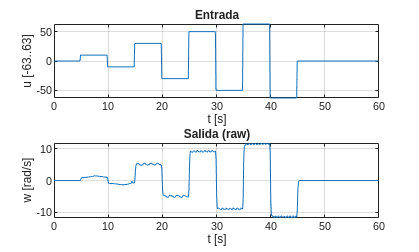

figure; 
subplot(2,1,1); 
plot(t_cmd, u); 
xlabel('t [s]'); 
ylabel('u [-63..63]'); 
title('Entrada');
grid on;  % Agregar grid al primer subplot

subplot(2,1,2); 
plot(t_odom, y); 
xlabel('t [s]'); 
ylabel('w [rad/s]'); 
title('Salida (raw)');
grid on;  % Agregar grid al segundo subplot

saveas(gcf, fullfile(save_plots_folder,'raw_signals.png'));

Modelamiento de la planta

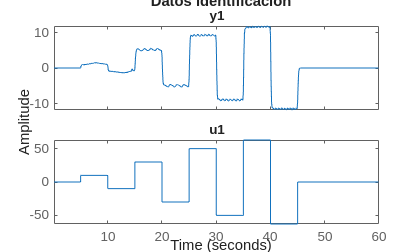

%% --- iddata ---
data_id = iddata(y_sync(:), u(:), Ts);  % y,u should be column vectors

figure; plot(data_id); title('Datos identificacion');
saveas(gcf, fullfile(save_plots_folder,'data_id.png'));


%% --- Estimate delay (optional) ---
% Estimar retardo con correlación cruzada
[XC, lags] = xcorr(y_sync - mean(y_sync), u - mean(u), 200, 'coeff');
[~, iMax] = max(XC);
lag_samples = lags(iMax);
delay_est = lag_samples * Ts;
fprintf('Delay estimate = %.4f s (lag = %d samples)\n', delay_est, lag_samples);

Delay estimate = 0.1000 s (lag = 1 samples)



%% --- Model estimation: probar varios metodos/ordenes ---
% ARX (orden 2)
na = 2; nb = 2; nk = max(0, round(delay_est/Ts)); % nk = delay en muestras
model_arx = arx(data_id, [na nb nk]);

% OE / TFEST (prueba 1er u 2do orden)
sys_tf1 = tfest(data_id, 1, 0, nk, 'Ts', Ts);
sys_tf2 = tfest(data_id, 2, 0, nk, 'Ts', Ts);

%sys_tf1_continuous = tfest(data_id, 1, 0, 'Ts', 0);
%sys_tf1 = c2d(sys_tf1_continuous, Ts, 'zoh');

%sys_tf2_continuous = tfest(data_id, 2, 0, 'Ts', 0); 
%sys_tf2 = c2d(sys_tf2_continuous, Ts, 'zoh');


Comparativa de modelos

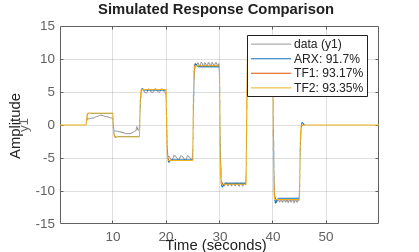

% Comparar ajustes
figure; 
compare(data_id, model_arx, sys_tf1, sys_tf2);
legend('data','ARX','TF1','TF2');
grid on;  % Agregar grid al gráfico de comparación
saveas(gcf, fullfile(save_plots_folder,'compare_models.png'));


% --- CÁLCULO SIMPLE Y ROBUSTO DE FIT ---
% Para ARX
[y_arx_sim] = compare(data_id, model_arx);
% Extraer datos numéricos de forma segura
if isa(y_arx_sim, 'iddata')
    try
        y_arx_data = y_arx_sim.OutputData;
    catch
        y_arx_data = y_arx_sim.y;
    end
else
    y_arx_data = y_arx_sim;
end

y_sync_vec = y_sync(:);
y_arx_vec = y_arx_data(:);

fit_arx = 100 * (1 - norm(y_sync_vec - y_arx_vec) / norm(y_sync_vec - mean(y_sync_vec)));
fprintf('Fit ARX: %.2f %%\n', fit_arx);

Fit ARX: 91.70 %




% --- AGREGAR CÁLCULO PARA TF1 ---
% Para TF1
[y_tf1_sim] = compare(data_id, sys_tf1);
if isa(y_tf1_sim, 'iddata')
    try
        y_tf1_data = y_tf1_sim.OutputData;
    catch
        y_tf1_data = y_tf1_sim.y;
    end
else
    y_tf1_data = y_tf1_sim;
end

y_tf1_vec = y_tf1_data(:);
fit_tf1 = 100 * (1 - norm(y_sync_vec - y_tf1_vec) / norm(y_sync_vec - mean(y_sync_vec)));
fprintf('Fit TF1: %.2f %%\n', fit_tf1);

Fit TF1: 93.17 %




% Para TF2
[y_tf2_sim] = compare(data_id, sys_tf2);
if isa(y_tf2_sim, 'iddata')
    try
        y_tf2_data = y_tf2_sim.OutputData;
    catch
        y_tf2_data = y_tf2_sim.y;
    end
else
    y_tf2_data = y_tf2_sim;
end

y_tf2_vec = y_tf2_data(:);
fit_tf2 = 100 * (1 - norm(y_sync_vec - y_tf2_vec) / norm(y_sync_vec - mean(y_sync_vec)));
fprintf('Fit TF2: %.2f %%\n', fit_tf2);

Fit TF2: 93.35 %


SELECCION DEL MODELO

%% --- Select model (ejemplo sys_tf2) ---
sysz = sys_tf2;  % si tfest devuelve discreto con Ts, está listo; si continuo -> c2d
if sysz.Ts == 0
    sysz = c2d(sysz, Ts, 'zoh');
end

% Parametros del modelo (numerador/denominador)
[numz, denz] = tfdata(sysz, 'v');
fprintf('\n=== FUNCIÓN DE TRANSFERENCIA DISCRETA ===\n');


=== FUNCIÓN DE TRANSFERENCIA DISCRETA ===


fprintf('G(z) = (');

G(z) = (

for i = 1:length(numz)
    if i > 1, fprintf(' + '); end
    fprintf('%.6g z^{%d}', numz(i), length(numz)-i);
end

0.111495 z^{2}

 + 

0 z^{1}

 + 

0 z^{0}

fprintf(') / (');

) / (

for i = 1:length(denz)
    if i > 1, fprintf(' + '); end
    fprintf('%.6g z^{%d}', denz(i), length(denz)-i);
end

1 z^{2}

 + 

-0.460124 z^{1}

 + 

0.0827519 z^{0}

fprintf(')\n');

)


%% =====================================================================
%%   ANÁLISIS COMPACTO DE PLANTA EN LAZO ABIERTO Y DISEÑO PID ÓPTIMO
%% =====================================================================
fprintf('\n==========================================================\n');

fprintf('     ANÁLISIS DE LA PLANTA Y SINTONIZACIÓN AUTOMÁTICA');

     ANÁLISIS DE LA PLANTA Y SINTONIZACIÓN AUTOMÁTICA

fprintf('\n==========================================================\n');


%% 1. ANÁLISIS TEMPORAL VECTORIZADO (Extracción de transitorio global)
duracion_escalon = 5.0; % Segundos reales por nivel según firmware
muestras_por_escalon = round(duracion_escalon / Ts);

% Segmentar la señal en ventanas estables (evitando transiciones iniciales)
idx_cambios = 1:muestras_por_escalon:length(u);
ts_vector = [];

for i = 1:(length(idx_cambios)-1)
    y_tramo = y_sync(idx_cambios(i):idx_cambios(i+1));
    if max(y_tramo) - min(y_tramo) < 0.5, continue; end % Ignorar reposo (u=0)
    
    % Valor final estacionario (promedio del último 20% del tramo)
    y_inf = mean(y_tramo(round(end*0.8):end));
    delta_y = y_inf - y_tramo(1);
    
    % Encontrar índice de establecimiento al 2% usando funciones lógicas vectoriales
    idx_ts = find(abs(y_tramo - y_inf) > 0.02 * abs(delta_y), 1, 'last');
    if ~isempty(idx_ts), ts_vector = [ts_vector; idx_ts * Ts]; end
end

ts_promedio = median(ts_vector); % Mediana robusta frente a ruidos/saturación
tau_temporal = ts_promedio / 4;
fprintf('>>> Métricas Temporales: Ts (2%%) = %.3f s | \\tau Est. = %.3f s\n', ts_promedio, tau_temporal);

>>> Métricas Temporales: Ts (2%) = 5.100 s | \tau Est. = 1.275 s



%% 2. ANÁLISIS DINÁMICO DEL MODELO IDENTIFICADO (sysz)
poles = pole(sysz);
[~, idx_dom] = max(abs(poles));
polo_dom = poles(idx_dom);

% Constante de tiempo discreta equivalente: \tau = -Ts / ln(|z|)
tau_equivalente = cond(abs(polo_dom) < 1, -Ts / log(abs(polo_dom)), tau_temporal);
fprintf('>>> Modelo Físico: Polo Dominante |z| = %.4f | \\tau Eq. = %.3f s\n', abs(polo_dom), tau_equivalente);

>>> Modelo Físico: Polo Dominante |z| = 0.2877 | \tau Eq. = 0.080 s



%% 3. DETERMINACIÓN CRÍTICA DE ESPECIFICACIONES (wc y PM)
% Frecuencia de cruce limitada por la dinámica temporal y Nyquist (\omega_max = \pi / (5*Ts))
wc_recomendado = min(4 / ts_promedio, pi / (5 * Ts)); 

% Lógica adaptativa para Margen de Fase basada en porcentaje de saturación (16.7%)
PM_recomendado = cond(16.7 > 10, 75, 65); 

% Mitigación del desfase del retardo de transporte inherente (0.1s)
delay_deg = (wc_recomendado * 0.1) * (180 / pi);

fprintf('\n>>> PARÁMETROS CRÍTICOS SELECCIONADOS:\n');


>>> PARÁMETROS CRÍTICOS SELECCIONADOS:


fprintf('    Frecuencia de corte deseada (wc): %.4f rad/s\n', wc_recomendado);

    Frecuencia de corte deseada (wc): 0.7843 rad/s


fprintf('    Margen de Fase Objetivo (PM):     %d° (Efectivo Neto: %.1f°)\n', PM_recomendado, PM_recomendado - delay_deg);

    Margen de Fase Objetivo (PM):     75° (Efectivo Neto: 70.5°)



%% 4. DISEÑO AUTOMÁTICO Y ACTUALIZACIÓN DEL PID
opts = pidtuneOptions('DesignFocus', 'reference-tracking', 'PhaseMargin', PM_recomendado);
C_sat = pidtune(sysz, 'PIDF', wc_recomendado, opts); % Reescritura directa del controlador

% Desplegar ganancias calculadas listas para firmware
fprintf('\n>>> VALORES DE IMPLEMENTACIÓN ACTUALIZADOS (C_sat):\n');


>>> VALORES DE IMPLEMENTACIÓN ACTUALIZADOS (C_sat):


fprintf('    Kp = %.6f | Ki = %.6f | Kd = %.6f | Tf = %.6f\n', C_sat.Kp, C_sat.Ki, C_sat.Kd, C_sat.Tf);

    Kp = 0.219398 | Ki = 4.387953 | Kd = 0.000000 | Tf = 0.000000



% Verificación analítica de bucle abierto
[~, Pm_check, ~, Wcp_check] = margin(series(ss(C_sat), ss(sysz)));
fprintf('    Verificación: PM Obtenido = %.2f° | wc Obtenida = %.4f rad/s -> ✅\n', Pm_check, Wcp_check);

    Verificación: PM Obtenido = 83.38° | wc Obtenida = 0.7845 rad/s -> ✅


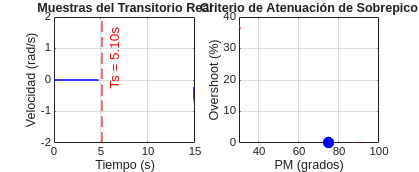


%% 5. GRAFICACIÓN DE JUSTIFICACIÓN CIENTÍFICA
figure('Name', 'Criterios de Sintonización', 'Position', [200 200 850 350]);
subplot(1,2,1);
plot(t_common(1:muestras_por_escalon*3), y_sync(1:muestras_por_escalon*3), 'b', 'LineWidth', 1.2);
xline(ts_promedio, 'r--', sprintf('Ts = %.2fs', ts_promedio), 'LineWidth', 1.2);
title('Muestras del Transitorio Real'); xlabel('Tiempo (s)'); ylabel('Velocidad (rad/s)'); grid on;

subplot(1,2,2);
pm_axis = 30:90; z_axis = pm_axis/100;
os_teorico = 100 * exp(-pi*z_axis./sqrt(1-z_axis.^2)); os_teorico(z_axis>=1) = 0;
plot(pm_axis, os_teorico, 'r', 'LineWidth', 1.5); hold on;
plot(PM_recomendado, 0, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
title('Criterio de Atenuación de Sobrepico'); xlabel('PM (grados)'); ylabel('Overshoot (%)'); grid on;
saveas(gcf, fullfile(save_plots_folder, 'justificacion_compacta.png'));


% Función auxiliar interna para operaciones condicionales compactas
function val = cond(tf, v_true, v_false)
    if tf, val = v_true; else, val = v_false; end
end

## --- REDISEÑO PID CONSIDERANDO SATURACIÓN ---

**1. Controlar la velocidad de respuesta (Ancho de Banda / Crossover Frequency)**

Por defecto, `pidtune` elige un tiempo de respuesta intermedio que considera seguro. Si quieres que el robot responda más rápido o más lento, debes definir explícitamente la **frecuencia de cruce** (en rad/s). A mayor frecuencia, el controlador será más agresivo.

Puedes modificar la línea de `pidtune` añadiendo esa frecuencia como tercer argumento:

Matlab

`% --- MODIFICACIÓN 1: Forzar velocidad del lazo ---`

`% Ejemplo: Especificar una frecuencia de cruce de 15 rad/s (prueba valores entre 5 y 30)`

`wc = ``15``; `

`C_sat = pidtune(sysz, ``'PIDF'``, wc, opts);`

- **Si el robot es muy lento:** Sube `wc` (ej. `wc = 20` o `25`).

- **Si el robot oscila o tiembla mucho:** Baja `wc` (ej. `wc = 5` o `10`).

**2. Cambiar el enfoque de diseño (**`DesignFocus`**)**

Actualmente usas `'balanced'`. Puedes cambiar drásticamente la prioridad del sintonizador modificando el parámetro de `pidtuneOptions`:

Matlab

`% --- MODIFICACIÓN 2: Cambiar la prioridad del algoritmo ---`

`% Opción A (Actual): Equilibrio entre seguir la referencia y rechazar perturbaciones`

`opts = pidtuneOptions(``'DesignFocus'``, ``'balanced'``); `

`% Opción B: Optimizado para seguir trayectorias suaves (reduce o elimina el overshoot)`

`opts = pidtuneOptions(``'DesignFocus'``, ``'reference-tracking'``); `

`% Opción C: Sintonización agresiva ante golpes externos (ideal si el robot lleva carga variable)`

`opts = pidtuneOptions(``'DesignFocus'``, ``'disturbance-rejection'``); `

**3. Ajustar los Márgenes de Estabilidad (Robustez frente al Sobreimpulso)**

Puedes exigirle a MATLAB que el diseño sea más "robusto". Esto obliga al algoritmo a mantener los polos alejados de la inestabilidad y **reduce directamente el sobreimpulso (Overshoot)** a costa de hacer el sistema ligeramente más lento.

Se modifica mediante la propiedad `PhaseMargin` (Margen de Fase en grados) dentro de `opts`:

Matlab

`% --- MODIFICACIÓN 3: Ajustar margen de fase (Por defecto suele ser 60) ---`

`opts = pidtuneOptions(``'DesignFocus'``, ``'balanced'``);`

`% Un margen de 75-80 grados reduce drásticamente el sobreimpulso (6.79% -> ~0%)`

`opts.PhaseMargin = ``75``; `

`C_sat = pidtune(sysz, ``'PIDF'``, opts);`

% Definir límites de saturación (deberían ser constantes conocidas)
u_min = -63;
u_max = 63;

% Diseñar PID con límites en mente
% Usar pidtune con especificaciones más realistas

wc_deseada = 0.09502;%0.095374;  % Entre 0.1 y 1.0
opts = pidtuneOptions('DesignFocus', 'reference-tracking', 'PhaseMargin', 85);
C_sat = pidtune(sysz, 'PIDF', wc_deseada, opts);

% Mostrar nuevo controlador
fprintf('\nPID considerando saturación:\n');


PID considerando saturación:


fprintf('  Kp = %.6f\n', C_sat.Kp);

  Kp = 0.026532


fprintf('  Ki = %.6f\n', C_sat.Ki);

  Ki = 0.530639


fprintf('  Kd = %.6f\n', C_sat.Kd);

  Kd = 0.000000


if isprop(C_sat, 'Tf')
    fprintf('  Tf = %.6f\n', C_sat.Tf);
end

  Tf = 0.000000



% Calcular parámetros clásicos
Kc = C_sat.Kp;
if C_sat.Ki ~= 0
    Ti = C_sat.Kp / C_sat.Ki;
else
    Ti = Inf;
end
if C_sat.Kp ~= 0 && C_sat.Kd ~= 0
    Td = C_sat.Kd / C_sat.Kp;
else
    Td = 0;
end

fprintf('\nFORMA CLÁSICA (Kc, Ti, Td):\n');


FORMA CLÁSICA (Kc, Ti, Td):


fprintf('  Kc = %.6f\n', Kc);

  Kc = 0.026532


if isfinite(Ti)
    fprintf('  Ti = %.6f s\n', Ti);
else
    fprintf('  Ti = Inf\n');
end

  Ti = 0.050000 s


fprintf('  Td = %.6f s\n', Td);

  Td = 0.000000 s



% Para implementación
fprintf('\nPARA IMPLEMENTACIÓN (Ts = %.4f s):\n', Ts);


PARA IMPLEMENTACIÓN (Ts = 0.1000 s):


if C_sat.Kd == 0
    % Solo PI
    fprintf('Forma PI discreto:\n');
    fprintf('  u[k] = u[k-1] + Kp*(e[k]-e[k-1]) + Ki*Ts*e[k]\n');
    fprintf('  u[k] = u[k-1] + %.6f*(e[k]-e[k-1]) + %.6f*e[k]\n', C_sat.Kp, C_sat.Ki*Ts);
else
    % PID completo
    fprintf('Forma PID discreto:\n');
    fprintf('  u[k] = u[k-1] + Kp*(e[k]-e[k-1]) + Ki*Ts*e[k] + (Kd/Ts)*(e[k]-2e[k-1]+e[k-2])\n');
    fprintf('  u[k] = u[k-1] + %.6f*(e[k]-e[k-1]) + %.6f*e[k] + %.6f*(e[k]-2e[k-1]+e[k-2])\n', C_sat.Kp, C_sat.Ki*Ts, C_sat.Kd/Ts);
end

Forma PI discreto:


  u[k] = u[k-1] + Kp*(e[k]-e[k-1]) + Ki*Ts*e[k]


  u[k] = u[k-1] + 0.026532*(e[k]-e[k-1]) + 0.053064*e[k]



dc = dcgain(sysz);
fprintf('Ganancia DC del modelo: %.4f\n', dc);

Ganancia DC del modelo: 0.1791


fprintf('Señal de control requerida para ref=10 => u_req = %.2f\n', 10/dc);

Señal de control requerida para ref=10 => u_req = 55.84


VISUALIZACION DEL PID

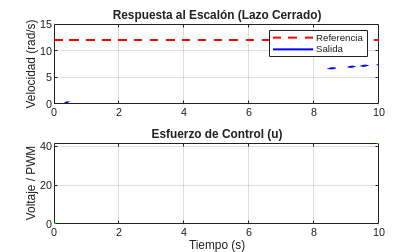

% --- Construir controlador discreto (pid object) con Ts CORRECTO
Ts = sysz.Ts;
Cd = C_sat;
% Convertir a espacio de estados si hay retrasos
sysz_ss = ss(sysz);
Cd_ss = ss(Cd);

% Construir y analizar
CL = feedback(series(Cd_ss, sysz_ss), 1);
info = stepinfo(CL, 'SettlingTimeThreshold', 0.02);


% Simular respuesta a referencia constante de 10 rad/s
t_sim = (0:Ts:10)'; % Aumentamos a 10s para ver si llega
ref = 12 * (t_sim >= 0); % Asegura el salto en t=0;
[y_cl, t_out] = lsim(CL, ref, t_sim);

e = ref - y_cl;
[u_cl, ~] = lsim(Cd, e, t_sim);


% También obtener la señal de control (u = Cd * (ref - y))
%e = ref - y_cl;
%[u_cl, ~] = lsim(Cd, e, t_sim);
figure('Name', 'Respuesta Temporal Lazo Cerrado');
subplot(2,1,1);
plot(t_out, ref, 'r--', t_out, y_cl, 'b-', 'LineWidth', 1.5);
grid on; title('Respuesta al Escalón (Lazo Cerrado)');
ylabel('Velocidad (rad/s)'); legend('Referencia','Salida');

subplot(2,1,2);
plot(t_out, u_cl, 'g-', 'LineWidth', 1.2);
grid on; title('Esfuerzo de Control (u)');
ylabel('Voltaje / PWM'); xlabel('Tiempo (s)');

MARGEN DE FASE

%% ==========================================================
%%        ANÁLISIS FRECUENCIAL: DIAGRAMAS DE BODE Y NYQUIST
%% ==========================================================
fprintf('\n==========================================================\n');

fprintf('         ANÁLISIS FRECUENCIAL EN LAZO ABIERTO (L(z))');

         ANÁLISIS FRECUENCIAL EN LAZO ABIERTO (L(z))

fprintf('\n==========================================================\n');


% 1. Definir el Lazo Abierto (L = Planta * Controlador)
% Convertimos a espacio de estados para manejar correctamente los retardos
L_ss = series(Cd_ss, sysz_ss);

% 2. Calcular los márgenes numéricos exactos de estabilidad
[Gm, Pm, Wcg, Wcp] = margin(L_ss);

% Convertir la ganancia de margen a Decibelios (dB)
Gm_db = 20*log10(Gm);

% Mostrar resultados numéricos por consola
fprintf('Margen de Fase (Phase Margin): %.2f grados\n', Pm);

Margen de Fase (Phase Margin): 89.20 grados


fprintf('Frecuencia de Cruce de Ganancia (wc): %.2f rad/s\n', Wcp);

Frecuencia de Cruce de Ganancia (wc): 0.10 rad/s


fprintf('Margen de Ganancia (Gain Margin): %.2f dB\n', Gm_db);

Margen de Ganancia (Gain Margin): 45.02 dB


fprintf('Frecuencia de Cruce de Fase: %.2f rad/s\n', Wcg);

Frecuencia de Cruce de Fase: 11.32 rad/s


fprintf('==========================================================\n');

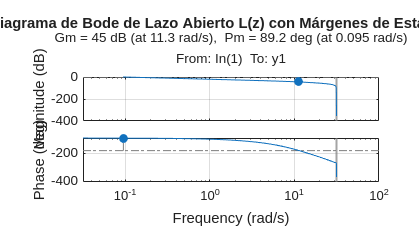


% --- Gráfico 1: DIAGRAMA DE BODE ---
figure('Name', 'Diagrama de Bode - Lazo Abierto', 'Units', 'normalized', 'Position', [0.2 0.2 0.5 0.5]);
margin(L_ss); % El comando 'margin' sin salidas grafica automáticamente con las líneas de margen
grid on;
title('Diagrama de Bode de Lazo Abierto L(z) con Márgenes de Estabilidad');

% Guardar gráfico de Bode
saveas(gcf, fullfile(save_plots_folder, 'bode_lazo_abierto.png'));

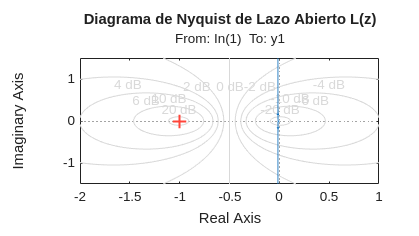


% --- Gráfico 2: DIAGRAMA DE NYQUIST ---
figure('Name', 'Diagrama de Nyquist - Lazo Abierto', 'Units', 'normalized', 'Position', [0.2 0.2 0.5 0.5]);
nyquist(L_ss);
grid on;
title('Diagrama de Nyquist de Lazo Abierto L(z)');

% Ajustar ejes para ver el punto crítico (-1, 0) con claridad
axis([-2 1 -1.5 1.5]); 

% Guardar gráfico de Nyquist
saveas(gcf, fullfile(save_plots_folder, 'nyquist_lazo_abierto.png'));

ANALIS DE ESTABILIDAD

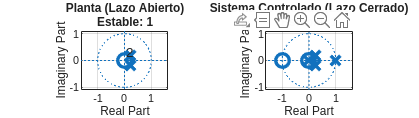

%% --- ANÁLISIS DE EVOLUCIÓN DE POLOS Y CEROS ---
% 1. Extraer datos de la Planta
[num_p, den_p] = tfdata(sysz, 'v');
poles_p = pole(sysz);
zeros_p = zero(sysz);

% 2. Extraer datos del Lazo Cerrado (Planta + PID)
[num_cl, den_cl] = tfdata(CL, 'v');
poles_cl = pole(delay2z(CL));
zeros_cl = zero(delay2z(CL));

figure('Name', 'Evolución de Polos y Ceros: Planta vs Lazo Cerrado', 'Units', 'normalized', 'Position', [0.1 0.0 0.8 0.4]);

% --- Subplot 1: Planta Sola ---
subplot(1,2,1);
zplane(num_p, den_p);
grid on; 
title(['Planta (Lazo Abierto)', newline, 'Estable: ', num2str(all(abs(poles_p) < 1))]);
% Modificar grosor de polos y ceros
h = findobj(gca, 'Type', 'line');
for i = 1:length(h)
    if strcmp(get(h(i), 'Marker'), 'o')  % Ceros
        set(h(i), 'LineWidth', 2.5, 'MarkerSize', 10);
    elseif strcmp(get(h(i), 'Marker'), 'x')  % Polos
        set(h(i), 'LineWidth', 2.5, 'MarkerSize', 10);
    end
end

% --- Subplot 2: Lazo Cerrado ---
subplot(1,2,2);
zplane(num_cl, den_cl);
grid on; 
title(['Sistema Controlado (Lazo Cerrado)', newline, 'Estable: ', num2str(all(abs(poles_cl) < 1))]);
% Modificar grosor de polos y ceros
h = findobj(gca, 'Type', 'line');
for i = 1:length(h)
    if strcmp(get(h(i), 'Marker'), 'o')  % Ceros
        set(h(i), 'LineWidth', 2.5, 'MarkerSize', 10);
    elseif strcmp(get(h(i), 'Marker'), 'x')  % Polos
        set(h(i), 'LineWidth', 2.5, 'MarkerSize', 10);
    end
end
saveas(gcf, fullfile(save_plots_folder,'evolucion_polos.png'));


%% --- COMPARATIVA NUMÉRICA EN CONSOLA ---
fprintf('\n==========================================================\n');

fprintf('       COMPARATIVA DE ESTABILIDAD (MAGNITUD |z|)');

       COMPARATIVA DE ESTABILIDAD (MAGNITUD |z|)

fprintf('\n==========================================================\n');


fprintf('\n[PLANTA ORIGINAL]\n');


[PLANTA ORIGINAL]


for i = 1:length(poles_p)
    fprintf(' Polo %d: %10.4f %+.4fj  | Magnitud: %.4f %s\n', ...
        i, real(poles_p(i)), imag(poles_p(i)), abs(poles_p(i)), ...
        char(9745*(abs(poles_p(i))<1) + 9888*(abs(poles_p(i))>=1)));
end

 Polo 1:     0.2301 +0.1727j  | Magnitud: 0.2877 ☑
 Polo 2:     0.2301 -0.1727j  | Magnitud: 0.2877 ☑



fprintf('\n[LAZO CERRADO (CON PID)]\n');


[LAZO CERRADO (CON PID)]


for i = 1:length(poles_cl)
    % Usamos un símbolo de check (v) o advertencia (x)
    status = 'OK'; if abs(poles_cl(i)) >= 1, status = '¡INESTABLE!'; end
    fprintf(' Polo %d: %10.4f %+.4fj  | Magnitud: %.4f -> %s\n', ...
        i, real(poles_cl(i)), imag(poles_cl(i)), abs(poles_cl(i)), status);
end

 Polo 1:     0.9904 +0.0000j  | Magnitud: 0.9904 -> OK
 Polo 2:     0.2334 +0.1706j  | Magnitud: 0.2891 -> OK
 Polo 3:     0.2334 -0.1706j  | Magnitud: 0.2891 -> OK
 Polo 4:    -0.0000 +0.0000j  | Magnitud: 0.0000 -> OK



% Análisis de "Cercanía al borde"
dist_borde = 1 - max(abs(poles_cl));
fprintf('\nDistancia del polo más lento al borde unitario: %.4f\n', dist_borde);


Distancia del polo más lento al borde unitario: 0.0096


fprintf('==========================================================\n');


%% --- RESUMEN FINAL DE DESEMPEÑO ---
fprintf('\nRESUMEN DE RESPUESTA TEMPORAL (PID):\n');


RESUMEN DE RESPUESTA TEMPORAL (PID):


fprintf(' - Tiempo de establecimiento (2%%): %.3f s\n', info.SettlingTime);

 - Tiempo de establecimiento (2%): 40.700 s


fprintf(' - Sobreimpulso (Overshoot):      %.2f %%\n', info.Overshoot);

 - Sobreimpulso (Overshoot):      0.00 %


fprintf(' - Tiempo de subida (RiseTime):    %.3f s\n', info.RiseTime);

 - Tiempo de subida (RiseTime):    22.800 s
